# 21.1

### 1. 

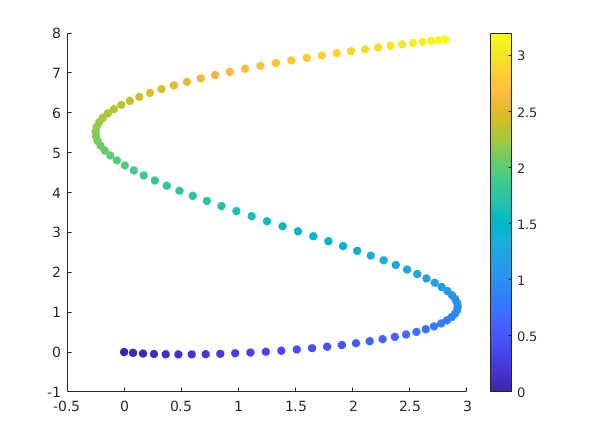

syms u
assume(u,["positive","real"])
r = 4 * [0.3960*cos(2.65 * (u + 1.4)); -0.99 * sin(u + 1.4); 0 * u];
r = simplify(r);

u_0 = 0;
u_max = 3.2;
u_num = linspace(u_0, u_max);
r_num = subs(r, u, u_num);
r_num(1,:) = r_num(1, :) - r_num(1,1);
r_num(2,:) = r_num(2, :) - r_num(2,1);

figure();
scatter(r_num(1, :), r_num(2, :), 36, u_num, "filled")
colorbar

### 2.

T_hat = simplify(diff(r,u)/norm(diff(r,u)));
N_hat = simplify(diff(T_hat,u)/norm(diff(T_hat,u)));
u_samples_indices = round(linspace(1, length(u_num), 5));
u_samples = u_num(u_samples_indices);
T_hat_samples = subs(T_hat, u, u_samples);
N_hat_samples = subs(N_hat, u, u_samples);

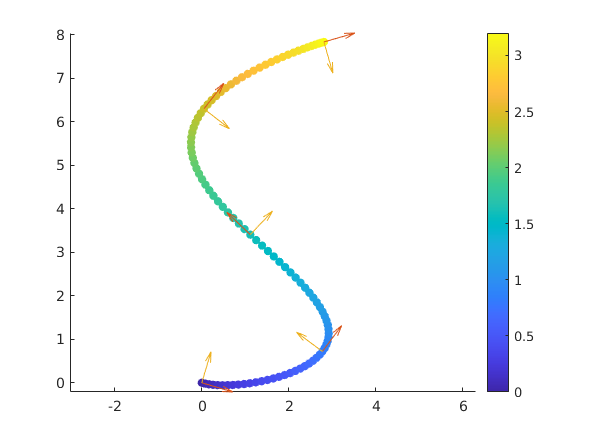

figure()
hold on
scatter(r_num(1, :), r_num(2, :), 36, u_num, "filled")
colorbar
quiver(r_num(1, u_samples_indices), r_num(2, u_samples_indices), T_hat_samples(1,:), T_hat_samples(2,:), 0.2)
quiver(r_num(1, u_samples_indices), r_num(2, u_samples_indices), N_hat_samples(1,:), N_hat_samples(2,:), 0.2)
axis equal

# 21.2

### 1.

syms beta t
assume([beta, t], "real")
r_t = subs(r, u, beta * t)

$$r\_t = \left(\begin{array}{c} \frac{198\,\cos\left(\frac{53\,\beta \,t}{20}+\frac{371}{100}\right)}{125}\\ -\frac{99\,\sin\left(\beta \,t+\frac{7}{5}\right)}{25}\\ 0 \end{array}\right)$$

vel = diff(r_t, t)

$$vel = \left(\begin{array}{c} -\frac{5247\,\beta \,\sin\left(\frac{53\,\beta \,t}{20}+\frac{371}{100}\right)}{1250}\\ -\frac{99\,\beta \,\cos\left(\beta \,t+\frac{7}{5}\right)}{25}\\ 0 \end{array}\right)$$

T_hat_t = subs(T_hat, u, beta*t);

vel_lin = dot(vel, T_hat_t)*T_hat_t;
vel_ang = cross(T_hat_t, diff(T_hat_t, t));

speed = norm(vel_lin);

sub_vals = struct();
sub_vals.beta = 0.2;
sub_vals.t = u_num/sub_vals.beta;

tspan = sub_vals.t;

speeds = subs(speed, sub_vals);
mat_omegas = eval(subs(vel_ang, sub_vals));
omegas = mat_omegas(3, :);

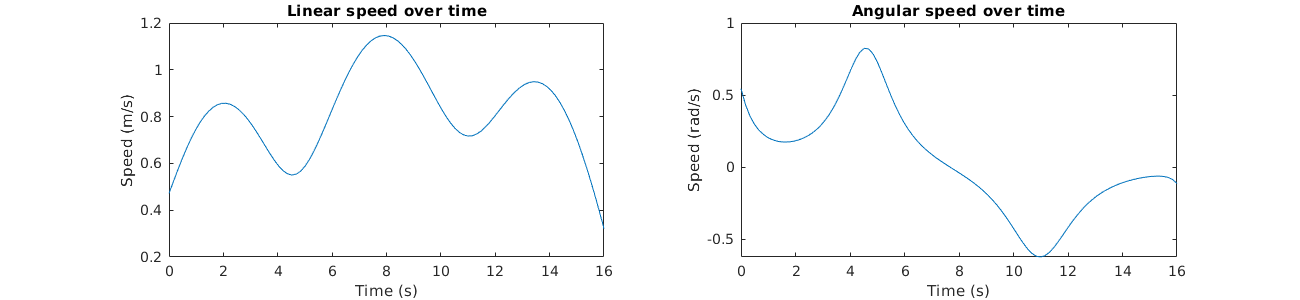

figure();
set(gcf, 'Position', [0, 0, 1300, 300])

subplot(1, 2, 1);
plot(tspan, speeds);
title("Linear speed over time")
xlabel("Time (s)")
ylabel("Speed (m/s)")

subplot(1, 2, 2);
plot(tspan, omegas);
title("Angular speed over time")
xlabel("Time (s)")
ylabel("Speed (rad/s)")

### 2.

bod_02beta = readtable("bod_0.2beta.csv");

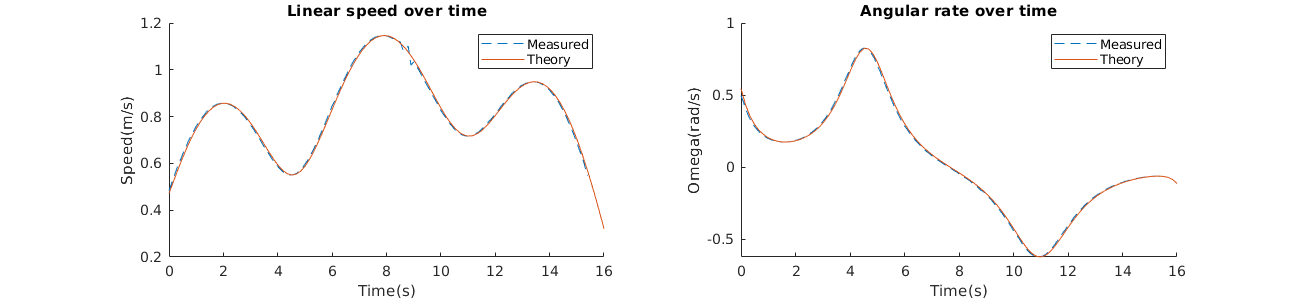

d = 0.235; % Robot wheel-to-wheel distance

% Pull the data out of the table
t_meas = bod_02beta.time_seconds_;
l_meas = bod_02beta.encoderLeft_meters_;
r_meas = bod_02beta.encoderRight_meters_;

% Numerically differentiate the data using Euler discretization
dt_meas = diff(t_meas);
v_l_meas = diff(l_meas) ./ dt_meas;
v_r_meas = diff(r_meas) ./ dt_meas;

% Calculate discrete speed and omega from measured left and right wheel
% speeds
speed_meas = (v_l_meas + v_r_meas) / 2;
omega_meas = (v_r_meas - v_l_meas) / d;

% Plot omega and speed over time
figure()
set(gcf, 'Position', [0, 0, 1300, 300]);

subplot(1, 2, 1)
hold on;
plot(t_meas(2:end) - t_meas(2), speed_meas, '--');
plot(tspan, speeds);
title("Linear speed over time")
xlabel("Time(s)")
ylabel("Speed(m/s)")
legend("Measured", "Theory")

subplot(1, 2, 2)
hold on
plot(t_meas(2:end) - t_meas(2), omega_meas, '--');
plot(tspan, omegas);
title("Angular rate over time")
xlabel("Time(s)")
ylabel("Omega(rad/s)")
legend("Measured", "Theory")

# 21.3

### 1.

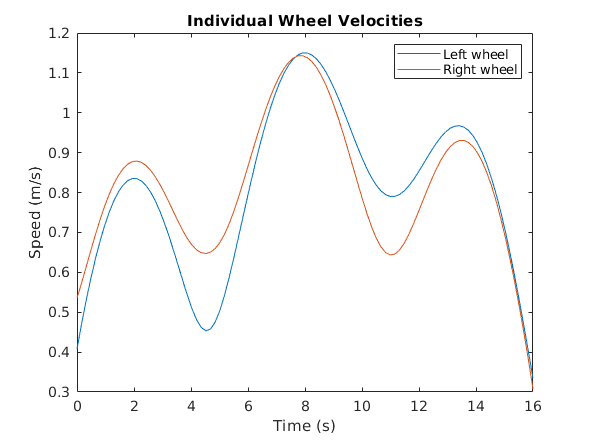

v_r = simplify(speed + vel_ang(3) * d / 2);
v_l = simplify(speed - vel_ang(3) * d / 2);

v_r_num = eval(subs(v_r,sub_vals));
v_l_num = eval(subs(v_l,sub_vals));

figure()
plot(tspan, v_l_num, tspan, v_r_num)
xlabel("Time (s)")
ylabel("Speed (m/s)")
legend("Left wheel", "Right wheel")
title("Theoretical Individual Wheel Velocities")

### 2.

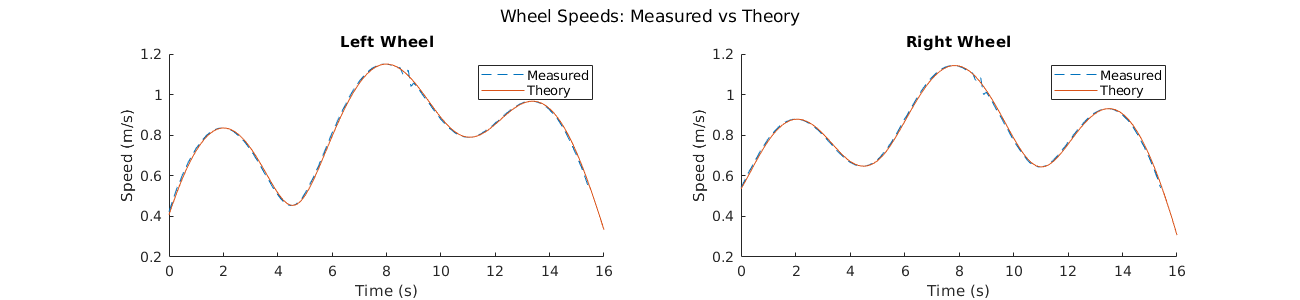

figure()
set(gcf, 'position', [0, 0, 1300, 300])
sgtitle("Wheel Speeds: Measured vs Theory")

subplot(1, 2, 1)
hold on
plot(t_meas(2:end) - t_meas(2), v_l_meas, '--');
plot(tspan, v_l_num);
title("Left Wheel")
xlabel("Time (s)")
ylabel("Speed (m/s)")
legend("Measured", "Theory")

subplot(1, 2, 2)
hold on
plot(t_meas(2:end) - t_meas(2), v_r_meas, '--');
plot(tspan, v_r_num);
title("Right Wheel")
xlabel("Time (s)")
ylabel("Speed (m/s)")
legend("Measured", "Theory")

# 21.4

starterCodeForBridgeOfDoomQEA2021();
% Create our publisher
pubvel = rospublisher('/raw_vel') 

% Create corresponding message struct
message = rosmessage(pubvel);  

% Set initial velocity to zero
message.Data = [0, 0]; 
send(pubvel, message);

% Create data object for sustituting in beta and t into our symbolic expression for wheel speeds    
struct_current_vals = struct();
struct_current_vals.beta = 0.2;

% Track elapsed time
elapsed = 0;
rostic;
while elapsed < 30
    elapsed = rostoc;

    % Substitute in elapsed time for t and calculate corresponding left and
    % right wheel speeds
    struct_current_vals.t = elapsed;
    v_l_current = eval(subs(v_l, struct_current_vals));
    v_r_current = eval(subs(v_r, struct_current_vals));
    
    % Publish
    message.Data = [v_l_current, v_r_current];
    send(pubvel, message);
end

# 21.5

### Numerical Integration

We can calculate the position and headings (the poses) of the neato through the following steps:

- Through simply numerically integrating the $\omega$'s, we can calculate the heading of the neato at each timestep

- Using the heading, we can then transform the velocity vector in the body frame to the world frame

- Finally, we can once again numerically integrate the velocity vectors in the world frame to find the positions

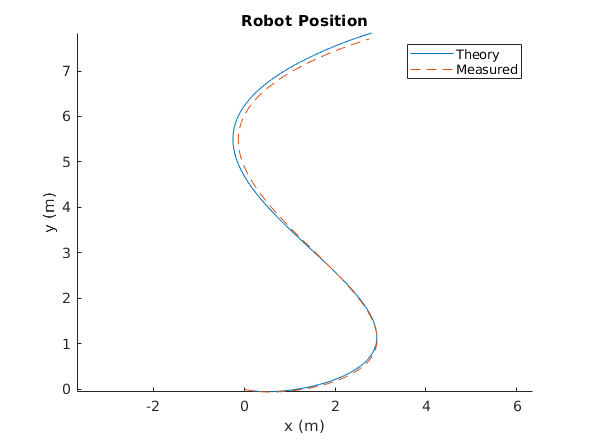

% Calculate initial heading of neato
theta_0 = atan(eval(T_hat_samples(2,1)/T_hat_samples(1,1)));

% Numerically integrate omegas to get heading(theta) over time
% Note that we add an offset of the initial theta
thetas = cumtrapz(t_meas(2:end), omega_meas) + theta_0;

% Preallocate velocity matrix
vel_meas = NaN(size(speed_meas,1), 2);

% Calculate velocity matrix
for i = 1:size(speed_meas,1)
    % The velocity vector at each point is the velocity in the body frame,
    % which is [speed; 0], rotated by the body->world rotation matrix
    %
    % This gives us the velocity vector in the world frame
    
    theta = thetas(i);
    rot_mat_body_to_world = [cos(theta), -sin(theta); sin(theta), cos(theta)];
    vel_meas(i,:) =  rot_mat_body_to_world * [speed_meas(i); 0];
end

% We can then numerically integrate the velocity vectors to calculate the
% position over time
pos_meas = cumtrapz(t_meas(2:end), vel_meas,1);

% Plotting
figure()
hold on
plot(r_num(1, :), r_num(2, :))
plot(pos_meas(:,1), pos_meas(:,2), "--")

axis equal
xlabel("x (m)")
ylabel("y (m)")
legend("Theory", "Measured")
title("Robot Position")

### Lie Integration

We can also do this integration using some basic Lie theory for robotics.

The neato's state is an element of the lie group SE(2):


$$M = \left[
\matrix{
cos(\theta) & -sin(\theta) & x \cr
sin(\theta) & cos(\theta) & y  \cr
0 & 0 & 1
}
\right]

\in 
SE(2)$$


The velocities and omegas that we measure are elements $m$ of the lie algebra of $SE(2)$: $\mathfrak{se}{2}$


$$m \in \mathfrak{se}(2)$$


$m$ has the following form:


$$\left[
\matrix{
0 & -\omega & \dot x_b \cr
\omega & 0 & \dot y_b  \cr
0 & 0 & 0
}
\right]
$$


Where $\dot x_b$ and $\dot y_b$ are the robot's velocities in the BODY frame.

We can use the exponential map (matrix exponential) $M = Exp(t \cdot m)$ to "integrate" the change in pose, given an initial set of linear and angular velocities, and over a certain timespan. We can then use Euler integration with Lie Groups: $M_{t+1} = M_t \cdot M_{\Delta t}$, where $M_\Delta = Exp(\Delta t \cdot m)$. 

For more on the method described here, see [here](https://arxiv.org/pdf/1812.01537.pdf). (https://arxiv.org/pdf/1812.01537.pdf)

To put all this math into matlab:

% Create our initial pose matrix (Element of SE2
pose_0 = [cos(theta_0), -sin(theta_0), 0;
          sin(theta_0), cos(theta_0),  0;
          0,            0,             1];

% Create a list of pose matrices, to track the pose over time
mat_poses = zeros(3, 3, length(omega_meas));
mat_poses(:, :, 1) = pose_0;

% Iterate through, applying the transformation at each step
for i = 2 : size(mat_poses, 3)
    dt = dt_meas(i);
    
    % Here is our lie-algebra matrix (the twist)
    % Note that our body frame y velocity is 0
    twist = [0,              -omega_meas(i-1), speed_meas(i-1);
             omega_meas(i-1), 0,               0;
             0,               0                0;];
    
    % M_{t+1} = M_t * M_{\Delta t}
    mat_poses(:, :, i) = mat_poses(:, :, i-1) * expm(twist*dt);
end

% Pull out the final positions
posns = reshape(mat_poses(1:2, 3, :), 2, size(mat_poses, 3))';

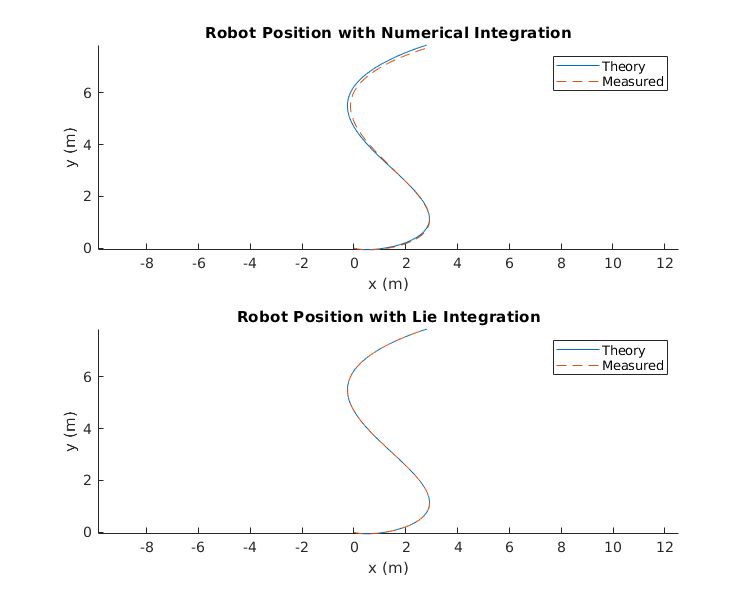

figure()
set(gcf, 'Position', [0, 0, 750, 600])

subplot(2, 1, 1)
hold on
plot(r_num(1, :), r_num(2, :))
plot(pos_meas(:,1), pos_meas(:,2), "--")

axis equal
xlabel("x (m)")
ylabel("y (m)")
legend("Theory", "Measured")
title("Robot Position with Numerical Integration")

subplot(2, 1, 2)
hold on
plot(r_num(1, :), r_num(2, :))
plot(posns(:, 1), posns(:, 2), '--')

axis equal
xlabel("x (m)")
ylabel("y (m)")
legend("Theory", "Measured")
title("Robot Position with Lie Integration")